# Exploring x/y data with gramm

In this example file, we will go further in exploring gramm's capabilities for data where some independent variables are continuous data.

To benefit from interactive elements, you should open it in MATLAB's editor with

We will load a partial dataset from a human movement science experiment

load example_movement.mat
T

T = 3170×15 table
    subject    session    trial_index    reference_direction    hit    m_movement_duration    m_dist    m_reaction_time                 target_pos                  valid_perc    valid_perc_session                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                       

In this dataset, we have four different subjects (`subject`), each coming for two sessions (`session`) on consecutive days at the lab. During each of these sessions they learn to control the displacement of a cursor on a screen, and their task is to reach targets with the cursor. The targets are arranged at discrete angles (`reference direction`) in a circle around a starting point. The cursor is difficult to control, and as a marker for progress, we record whether they reach the target in time (`hit`), how long was their reaction time (`m_reaction_time`), their movement (`m_movement_duration`), and what was the distance covered by the cursor (`m_dist`). Each line corresponds to a trial (`trial_index`), and we transformed the index in percentage of time elapsed within session (`valid_perc`) or across sessions (`valid_perc_session`).

## Continuous data

Here we will represent the evolution of the reaction time across trials for each subject (using `facet_grid()`). To treat sessions independently we will map them to color. 

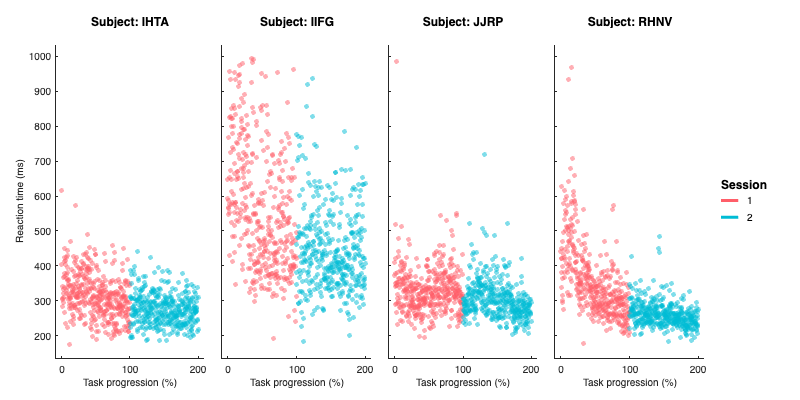

figure('Position',[100 100 800 400])

g=gramm('x',T.valid_perc_session,'y',T.m_reaction_time,'color',T.session);
g.facet_grid([],T.subject);
g.geom_point('alpha',0.5);
g.set_names('x','Task progression (%)','y','Reaction time (ms)','color','Session','column','Subject');
g.draw();

The points indicate a tendency for a decrease of the reaction time in all subjects, that tends to taper off in the second session. How can we add statistical layers that will help us visualize this ?

### Statistical layers for continuous data

There are several stat_ layers that allow this, they can be selected with the first drop-down menu.

#### stat_summary()

The most basic approach is simply to bin data across the x-axis and represent descriptive statistics like the mean reaction time and its confidence interval in each bin. This can be done with `stat_summary()` using the `'bin_in' `argument which value sets the total number of bins across the x axis.

#### stat_smooth()

This uses a smoothing approach, either with a built-in fast smoothing or using underlying matlab tools from the curve fitting toolbox (splines, moving averages, loess, etc.). The `'lambda' `parameter sets the smoothing intensity. The confidence interval is computed by bootstrap

#### stat_glm()

This uses a generalized linear model (fitglm() from the statistics toolbox), which by default is configured as a classical linear regression. Here we use an inverse gaussian distribution which is adapted to reaction time data.

- The `'distribution' `parameter allows to pick the distribution of the response variable and corresponding link function. 

- When `'disp_fit'` is set to true, the model equation is displayed in the figure as well as significance stars for each term

- `'fullrange'` determines wheter the fit is displayed across the complete range of the x axis or only the data range.

#### stat_fit()

This uses an anonymous function to fit any non-linear model. Here we use an exponential function provided with the `'fun'` argument.  This function requires starting values for the fit parameters with `'StartPoint'`.

- `'intopt'` sets whether the shaded area represents the uncertainty of data or of the fitted function.

- When `'disp_fit'` is set to true, the model equation is displayed in the figure

 By default this method uses `fit()` from the curve fitting toolbox but can be configured to use `fitnlm()` from the statistics toolbox. 

**Pick the stat_ layer :**

vis = "stat_glm";

All these layers use a common 'geom' argument to specify how the results are displayed. Select one with this drop-down menu:

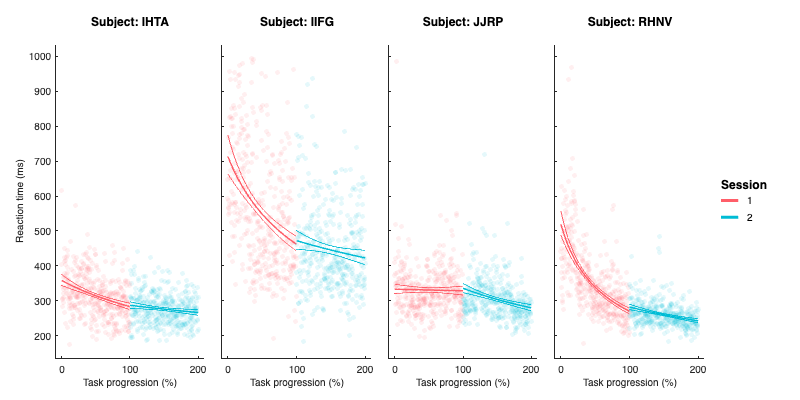

geom = 'lines';

figure('Position',[100 100 800 400])
g=gramm('x',T.valid_perc_session,'y',T.m_reaction_time,'color',T.session);
g.facet_grid([],T.subject);
g.geom_point('alpha',0.1);

switch vis                      %Call the correct gramm method depending on the chosen visualization
    case "stat_summary"
        g.stat_summary('geom',geom,'bin_in',10);
    case "stat_smooth"
        g.stat_smooth('geom',geom,'lambda',1e5);
    case "stat_glm"
        g.stat_glm('geom',geom,'distribution','inverse gaussian','disp_fit',false,'fullrange',false);
    case "stat_fit"
        g.stat_fit('geom',geom,'fun',@(a,b,c,x)a.*exp(x.*b)+c,'StartPoint',[1000 -0.01 150],'intopt','functional','disp_fit',false);
end

g.set_names('x','Task progression (%)','y','Reaction time (ms)','color','Session','column','Subject');
g.draw();

%Export
g.export('file_name','xy_export','file_type','png');

## Clustered data

In the previous section, we explored data where an underlying y=f(x) is assumed. gramm also proposes tools to explore x/y (and even z) data that corresponds to clusters or groupings. 

First we will compute the midpoints of all cursor trajectories (see [TimeSeries.mlx](matlab:open('./TimeSeries.mlx')))

T.xmid = cellfun(@(x)x(floor(length(x)/2)),T.px);
T.ymid = cellfun(@(x)x(floor(length(x)/2)),T.py);

We will examine the evolution of those midpoints between the first and second experimental session for all subjects. Use the picker below to chose a visualization

- `geom_point() `to view raw datapoints

- `stat_ellipse()` to plot the center of each group and uncertainty ellipse (computed here as a 95% confidence interval on the center, with the hypothesis of a bivariate normal distribution)

- `stat_bin2d() `to plot a 2D histogram

To note:

- With `geom_point()` we used `set_point_options()` to use smaller points due to the large number of points

- Here we use the `'lightness'` aesthetic to display session and pick a different default colormap with `set_color_options()`. Not all colormaps support lightness so only two are pickable.

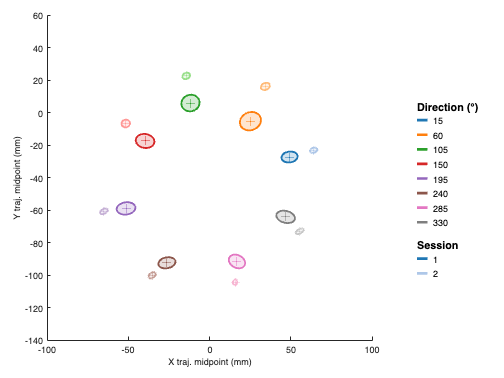

vis = "stat_ellipse";

figure
g=gramm('x',T.xmid,'y',T.ymid,'group',T.reference_direction,'lightness',T.session,'color',T.reference_direction);
switch vis
    case "geom_point"
        g.geom_point();
        g.set_point_options('base_size',3);
    case "stat_ellipse"
        g.stat_ellipse('type','ci');
    case "stat_bin2d"
        g=gramm('x',T.xmid,'y',T.ymid);
        g.facet_grid([],T.session);
        g.stat_bin2d('geom','image','edges',{[-100:10:100],[-140:10:60]});
end
g.axe_property('DataAspectRatio',[1 1 1],'XLim',[-100 100],'YLim',[-140 60]);
g.set_color_options('map','d3_20');
g.set_names('x','X traj. midpoint (mm)','y','Y traj. midpoint (mm)','color','Direction (°)','column','Session','lightness','Session');
g.draw();

This figure demonstrates that on the second day, the subjects are less variable in their movements and go further along the target direction at the midpoint of the movement.